# Kinect Camera Point Cloud Processing

David Olson, 13 Sep 2021

% Start Fresh
close all
clear all
clc

% Add Function Folders
addpath("User_Functions")

## Load Desired Data Set

% Load Data
load("SBT_CCW_lowRes.mat")

% Clear Unused Variables
clear accel dt Fs gyro odo t

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

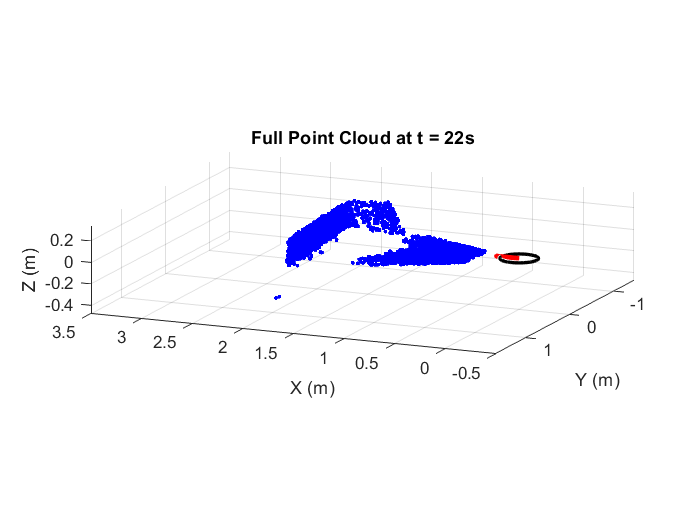

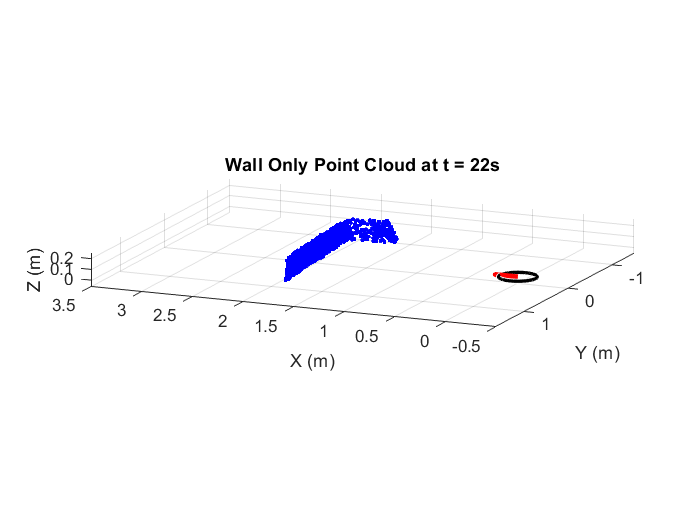

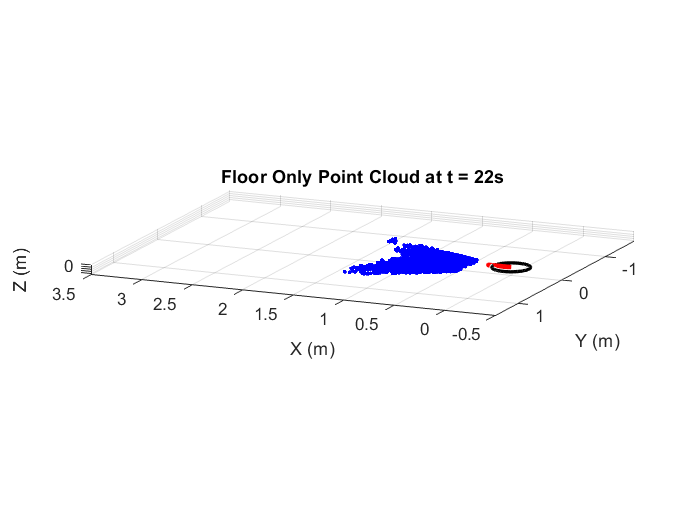

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = true;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% Verify Good Floor Data
test_frame = 22;
plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])

% Pitch of two Example Points
atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi

ans = -0.3475

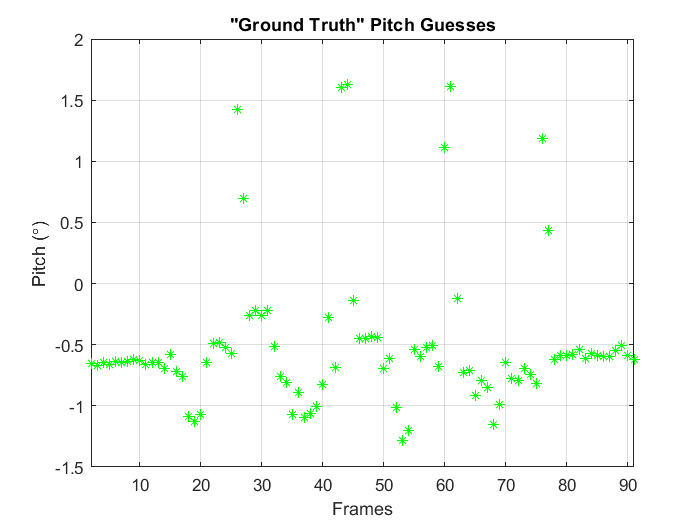

% Accomplish Crude Prediction of "Ground Truth" Pitch Values
pitch = zeros(1, num_frames);
for n = 2 : num_frames
    
    % Grab and Average All Points between x = 0.5 & x = 0.6
    xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
    xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
    
    % Grab and Average All Points between x = 0.9 & x = 0.1
    xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
    xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
    
    pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
    
end

% Plot "Ground Truth" Estimate of Pitch
plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
title('"Ground Truth" Pitch Guesses')
xlabel('Frames')
xlim([2 num_frames])
ylabel('Pitch (\circ)')
grid on

## Shift Wall and Floor Point Clouds to the Origin

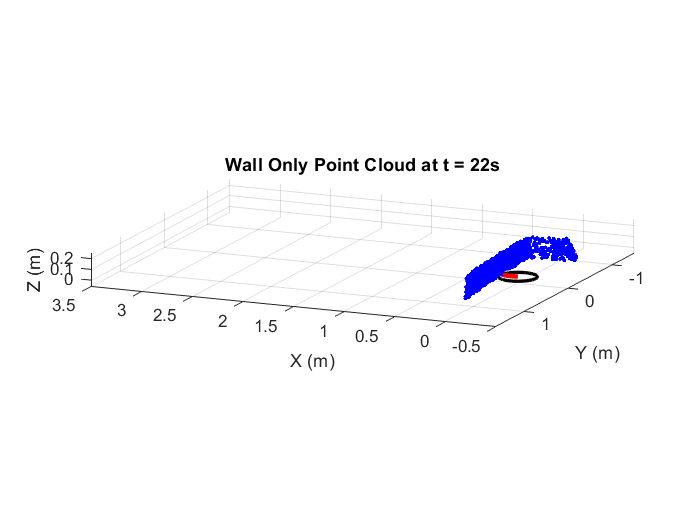

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = true;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.387215 seconds.


Begin Processing Frame #3

Elapsed time is 1.339879 seconds.


Begin Processing Frame #4

Elapsed time is 1.386095 seconds.


Begin Processing Frame #5

Elapsed time is 1.350815 seconds.


Begin Processing Frame #6

Elapsed time is 1.427821 seconds.


Begin Processing Frame #7

Elapsed time is 1.360506 seconds.


Begin Processing Frame #8

Elapsed time is 1.348747 seconds.


Begin Processing Frame #9

Elapsed time is 1.345018 seconds.


Begin Processing Frame #10

Elapsed time is 1.341451 seconds.


Begin Processing Frame #11

Elapsed time is 1.325789 seconds.


Begin Processing Frame #12

Elapsed time is 1.371554 seconds.


Begin Processing Frame #13

Elapsed time is 1.342934 seconds.


Begin Processing Frame #14

Elapsed time is 1.365761 seconds.


Begin Processing Frame #15

Elapsed time is 1.372255 seconds.


Begin Processing Frame #16

Elapsed time is 1.356477 seconds.


Begin Processing Frame #17

Elapsed time is 1.308181 seconds.


Begin Processing Frame #18

Elapsed time is 1.084791 seconds.


Begin Processing Frame #19

Elapsed time is 1.040934 seconds.


Begin Processing Frame #20

Elapsed time is 1.041314 seconds.


Begin Processing Frame #21

Elapsed time is 1.008201 seconds.


Begin Processing Frame #22

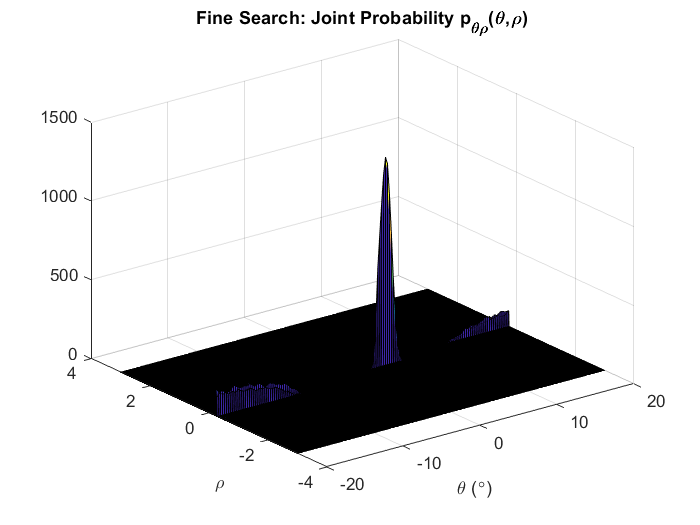

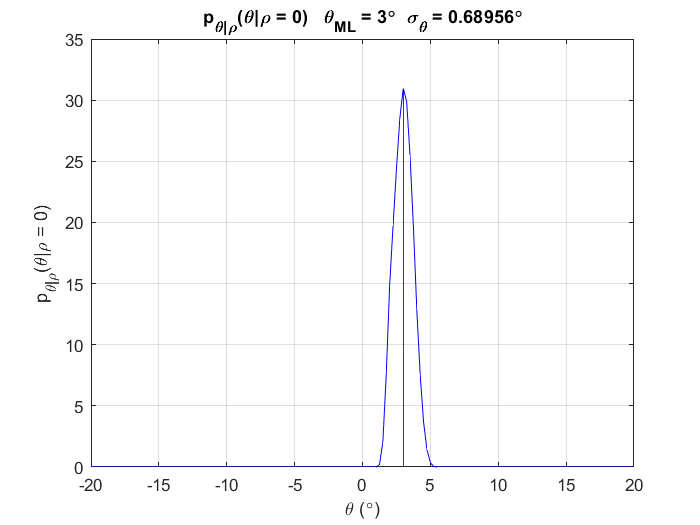

Elapsed time is 1.246184 seconds.


Begin Processing Frame #23

Elapsed time is 0.944485 seconds.


Begin Processing Frame #24

Elapsed time is 0.966916 seconds.


Begin Processing Frame #25

Elapsed time is 0.857128 seconds.


Begin Processing Frame #26

Elapsed time is 0.784394 seconds.


Begin Processing Frame #27

Elapsed time is 0.851139 seconds.


Begin Processing Frame #28

Elapsed time is 1.240597 seconds.


Begin Processing Frame #29

Elapsed time is 1.505998 seconds.


Begin Processing Frame #30

Elapsed time is 1.414387 seconds.


Begin Processing Frame #31

Elapsed time is 1.372576 seconds.


Begin Processing Frame #32

Elapsed time is 1.397420 seconds.


Begin Processing Frame #33

Elapsed time is 1.434469 seconds.


Begin Processing Frame #34

Elapsed time is 1.358843 seconds.


Begin Processing Frame #35

Elapsed time is 1.045608 seconds.


Begin Processing Frame #36

Elapsed time is 1.063274 seconds.


Begin Processing Frame #37

Elapsed time is 1.061111 seconds.


Begin Processing Frame #38

Elapsed time is 1.018720 seconds.


Begin Processing Frame #39

Elapsed time is 1.022436 seconds.


Begin Processing Frame #40

Elapsed time is 0.936897 seconds.


Begin Processing Frame #41

Elapsed time is 0.966714 seconds.


Begin Processing Frame #42

Elapsed time is 0.836091 seconds.


Begin Processing Frame #43

Elapsed time is 0.729632 seconds.


Begin Processing Frame #44

Elapsed time is 0.793945 seconds.


Begin Processing Frame #45

Elapsed time is 1.033476 seconds.


Begin Processing Frame #46

Elapsed time is 1.341596 seconds.


Begin Processing Frame #47

Elapsed time is 1.346675 seconds.


Begin Processing Frame #48

Elapsed time is 1.356074 seconds.


Begin Processing Frame #49

Elapsed time is 1.461867 seconds.


Begin Processing Frame #50

Elapsed time is 1.417670 seconds.


Begin Processing Frame #51

Elapsed time is 1.419345 seconds.


Begin Processing Frame #52

Elapsed time is 1.259518 seconds.


Begin Processing Frame #53

Elapsed time is 1.127511 seconds.


Begin Processing Frame #54

Elapsed time is 1.078465 seconds.


Begin Processing Frame #55

Elapsed time is 1.089450 seconds.


Begin Processing Frame #56

Elapsed time is 1.055626 seconds.


Begin Processing Frame #57

Elapsed time is 0.985353 seconds.


Begin Processing Frame #58

Elapsed time is 0.935871 seconds.


Begin Processing Frame #59

Elapsed time is 0.969341 seconds.


Begin Processing Frame #60

Elapsed time is 0.803197 seconds.


Begin Processing Frame #61

Elapsed time is 0.773939 seconds.


Begin Processing Frame #62

Elapsed time is 0.959627 seconds.


Begin Processing Frame #63

Elapsed time is 1.426562 seconds.


Begin Processing Frame #64

Elapsed time is 1.414942 seconds.


Begin Processing Frame #65

Elapsed time is 1.432354 seconds.


Begin Processing Frame #66

Elapsed time is 1.396400 seconds.


Begin Processing Frame #67

Elapsed time is 1.365080 seconds.


Begin Processing Frame #68

Elapsed time is 1.117916 seconds.


Begin Processing Frame #69

Elapsed time is 1.077831 seconds.


Begin Processing Frame #70

Elapsed time is 1.069389 seconds.


Begin Processing Frame #71

Elapsed time is 0.996013 seconds.


Begin Processing Frame #72

Elapsed time is 0.980231 seconds.


Begin Processing Frame #73

Elapsed time is 0.910313 seconds.


Begin Processing Frame #74

Elapsed time is 0.963468 seconds.


Begin Processing Frame #75

Elapsed time is 0.833061 seconds.


Begin Processing Frame #76

Elapsed time is 0.696950 seconds.


Begin Processing Frame #77

Elapsed time is 0.848218 seconds.


Begin Processing Frame #78

Elapsed time is 1.194728 seconds.


Begin Processing Frame #79

Elapsed time is 1.493652 seconds.


Begin Processing Frame #80

Elapsed time is 1.452830 seconds.


Begin Processing Frame #81

Elapsed time is 1.525106 seconds.


Begin Processing Frame #82

Elapsed time is 1.436053 seconds.


Begin Processing Frame #83

Elapsed time is 1.534614 seconds.


Begin Processing Frame #84

Elapsed time is 1.489597 seconds.


Begin Processing Frame #85

Elapsed time is 1.512961 seconds.


Begin Processing Frame #86

Elapsed time is 1.452150 seconds.


Begin Processing Frame #87

Elapsed time is 1.477074 seconds.


Begin Processing Frame #88

Elapsed time is 1.458725 seconds.


Begin Processing Frame #89

Elapsed time is 1.454078 seconds.


Begin Processing Frame #90

Elapsed time is 1.454289 seconds.


Begin Processing Frame #91

Elapsed time is 1.494776 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

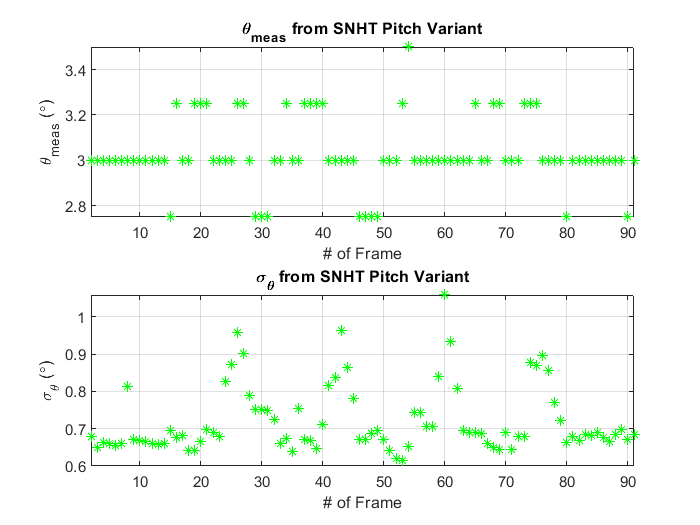

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.767274 seconds.


Begin Processing Frame #3

Elapsed time is 0.694692 seconds.


Begin Processing Frame #4

Elapsed time is 0.606431 seconds.


Begin Processing Frame #5

Elapsed time is 0.613851 seconds.


Begin Processing Frame #6

Elapsed time is 0.732595 seconds.


Begin Processing Frame #7

Elapsed time is 0.771307 seconds.


Begin Processing Frame #8

Elapsed time is 0.678759 seconds.


Begin Processing Frame #9

Elapsed time is 0.649291 seconds.


Begin Processing Frame #10

Elapsed time is 0.718911 seconds.


Begin Processing Frame #11

Elapsed time is 0.762570 seconds.


Begin Processing Frame #12

Elapsed time is 0.662164 seconds.


Begin Processing Frame #13

Elapsed time is 0.651734 seconds.


Begin Processing Frame #14

Elapsed time is 0.621921 seconds.


Begin Processing Frame #15

Elapsed time is 0.630290 seconds.


Begin Processing Frame #16

Elapsed time is 0.743548 seconds.


Begin Processing Frame #17

Elapsed time is 1.030008 seconds.


Begin Processing Frame #18

Elapsed time is 2.525659 seconds.


Begin Processing Frame #19

Elapsed time is 2.806850 seconds.


Begin Processing Frame #20

Elapsed time is 2.365312 seconds.


Begin Processing Frame #21

Elapsed time is 2.944414 seconds.


Begin Processing Frame #22

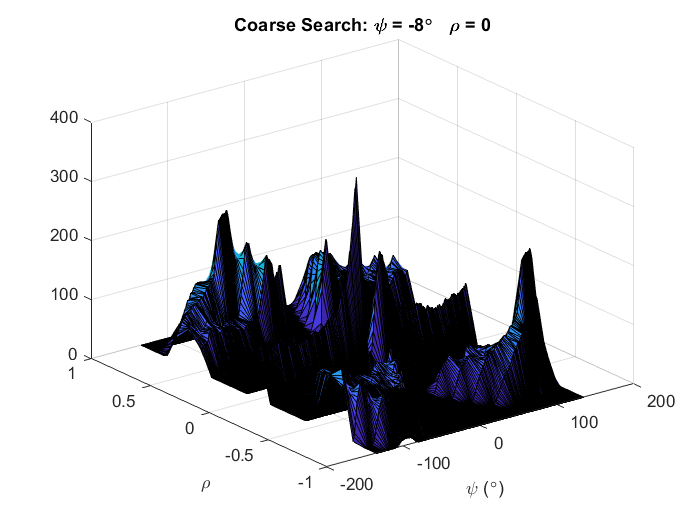

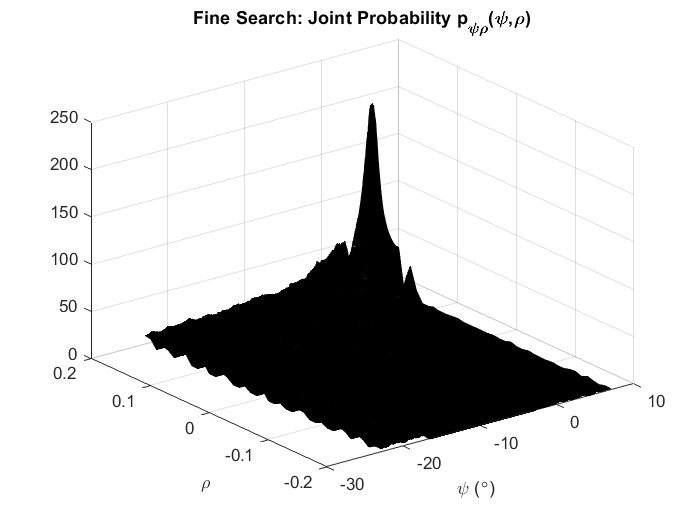

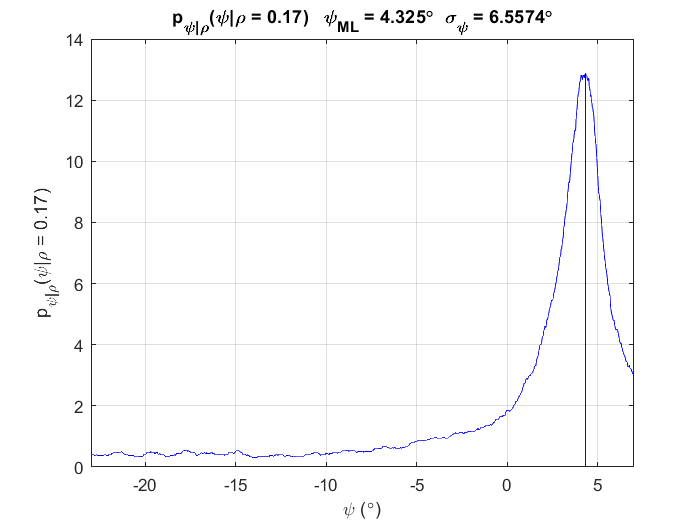

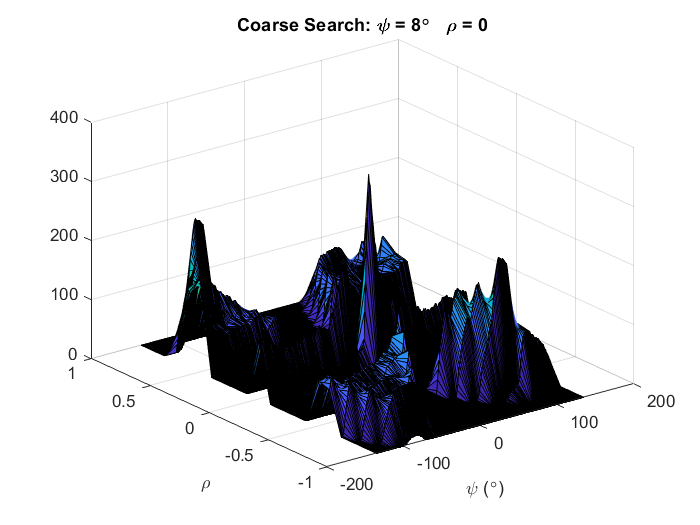

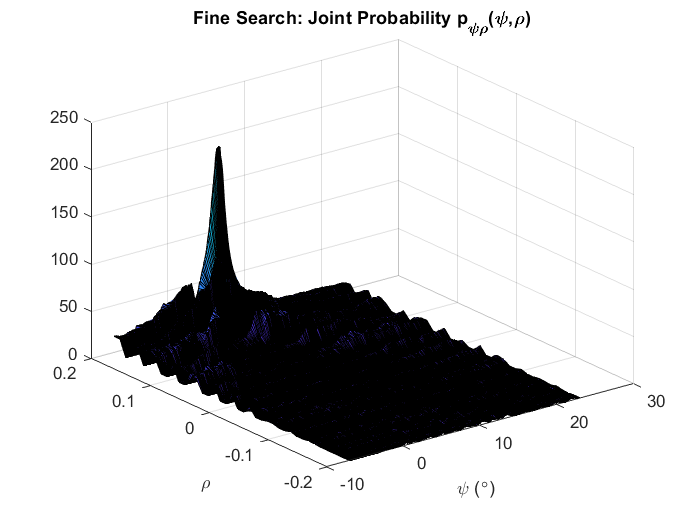

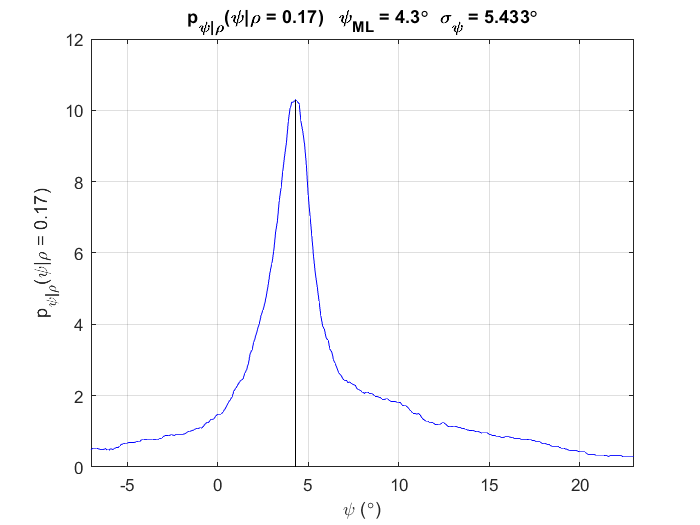

Elapsed time is 3.480115 seconds.


Begin Processing Frame #23

Elapsed time is 3.405844 seconds.


Begin Processing Frame #24

Elapsed time is 4.079946 seconds.


Begin Processing Frame #25

Elapsed time is 4.831550 seconds.


Begin Processing Frame #26

Elapsed time is 5.319147 seconds.


Begin Processing Frame #27

Elapsed time is 4.998593 seconds.


Begin Processing Frame #28

Elapsed time is 1.518194 seconds.


Begin Processing Frame #29

Elapsed time is 0.381661 seconds.


Begin Processing Frame #30

Elapsed time is 0.408276 seconds.


Begin Processing Frame #31

Elapsed time is 0.407847 seconds.


Begin Processing Frame #32

Elapsed time is 0.424607 seconds.


Begin Processing Frame #33

Elapsed time is 0.407335 seconds.


Begin Processing Frame #34

Elapsed time is 0.597513 seconds.


Begin Processing Frame #35

Elapsed time is 1.980561 seconds.


Begin Processing Frame #36

Elapsed time is 2.475718 seconds.


Begin Processing Frame #37

Elapsed time is 2.345025 seconds.


Begin Processing Frame #38

Elapsed time is 2.654954 seconds.


Begin Processing Frame #39

Elapsed time is 2.782682 seconds.


Begin Processing Frame #40

Elapsed time is 3.224836 seconds.


Begin Processing Frame #41

Elapsed time is 4.114780 seconds.


Begin Processing Frame #42

Elapsed time is 5.039683 seconds.


Begin Processing Frame #43

Elapsed time is 5.808474 seconds.


Begin Processing Frame #44

Elapsed time is 5.186420 seconds.


Begin Processing Frame #45

Elapsed time is 3.700891 seconds.


Begin Processing Frame #46

Elapsed time is 0.901456 seconds.


Begin Processing Frame #47

Elapsed time is 0.724215 seconds.


Begin Processing Frame #48

Elapsed time is 1.001989 seconds.


Begin Processing Frame #49

Elapsed time is 0.393870 seconds.


Begin Processing Frame #50

Elapsed time is 0.422376 seconds.


Begin Processing Frame #51

Elapsed time is 0.454249 seconds.


Begin Processing Frame #52

Elapsed time is 2.221395 seconds.


Begin Processing Frame #53

Elapsed time is 2.276731 seconds.


Begin Processing Frame #54

Elapsed time is 2.891439 seconds.


Begin Processing Frame #55

Elapsed time is 2.517582 seconds.


Begin Processing Frame #56

Elapsed time is 2.805853 seconds.


Begin Processing Frame #57

Elapsed time is 2.987733 seconds.


Begin Processing Frame #58

Elapsed time is 3.560923 seconds.


Begin Processing Frame #59

Elapsed time is 4.222881 seconds.


Begin Processing Frame #60

Elapsed time is 5.075242 seconds.


Begin Processing Frame #61

Elapsed time is 5.829813 seconds.


Begin Processing Frame #62

Elapsed time is 4.254057 seconds.


Begin Processing Frame #63

Elapsed time is 0.401525 seconds.


Begin Processing Frame #64

Elapsed time is 0.523913 seconds.


Begin Processing Frame #65

Elapsed time is 0.500471 seconds.


Begin Processing Frame #66

Elapsed time is 0.440219 seconds.


Begin Processing Frame #67

Elapsed time is 0.996694 seconds.


Begin Processing Frame #68

Elapsed time is 2.016836 seconds.


Begin Processing Frame #69

Elapsed time is 2.879975 seconds.


Begin Processing Frame #70

Elapsed time is 2.701569 seconds.


Begin Processing Frame #71

Elapsed time is 2.808327 seconds.


Begin Processing Frame #72

Elapsed time is 2.963998 seconds.


Begin Processing Frame #73

Elapsed time is 3.606254 seconds.


Begin Processing Frame #74

Elapsed time is 3.995043 seconds.


Begin Processing Frame #75

Elapsed time is 4.929834 seconds.


Begin Processing Frame #76

Elapsed time is 5.862368 seconds.


Begin Processing Frame #77

Elapsed time is 5.189036 seconds.


Begin Processing Frame #78

Elapsed time is 2.234897 seconds.


Begin Processing Frame #79

Elapsed time is 0.164820 seconds.


Begin Processing Frame #80

Elapsed time is 0.212943 seconds.


Begin Processing Frame #81

Elapsed time is 0.218665 seconds.


Begin Processing Frame #82

Elapsed time is 0.219070 seconds.


Begin Processing Frame #83

Elapsed time is 0.205884 seconds.


Begin Processing Frame #84

Elapsed time is 0.206012 seconds.


Begin Processing Frame #85

Elapsed time is 0.209139 seconds.


Begin Processing Frame #86

Elapsed time is 0.207623 seconds.


Begin Processing Frame #87

Elapsed time is 0.228487 seconds.


Begin Processing Frame #88

Elapsed time is 0.211309 seconds.


Begin Processing Frame #89

Elapsed time is 0.228330 seconds.


Begin Processing Frame #90

Elapsed time is 0.228461 seconds.


Begin Processing Frame #91

Elapsed time is 0.226026 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

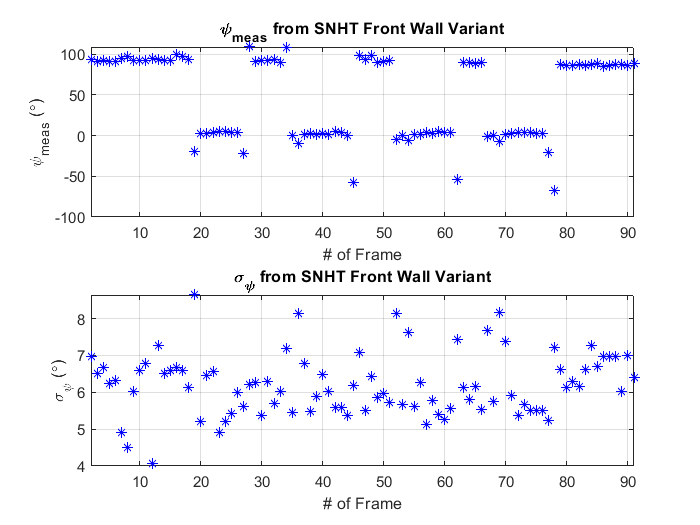

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

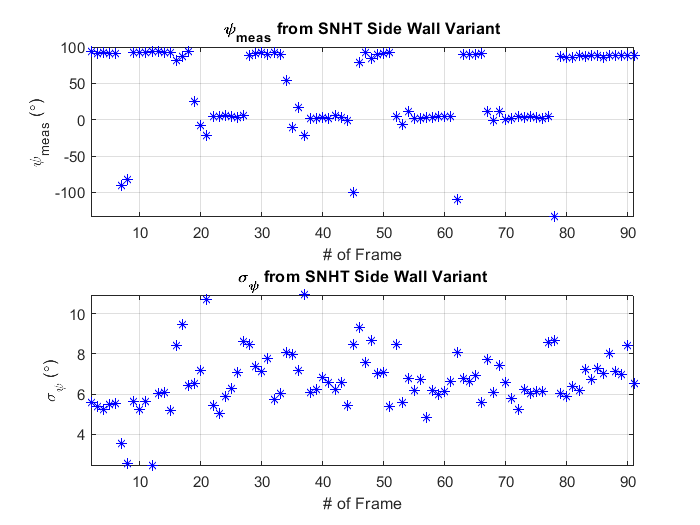

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save SNHT Data

% Save Data
save('SBT_CCW_SNHT_Results', 'theta_meas', 'theta_sigmas', ...
     'psi_fw_meas', 'psi_fw_sigmas', 'psi_sw_meas', 'psi_sw_sigmas')